**System 3**

a=19;
b=8;
c=a+b;

**Lead Compensator**

G3=tf([7*c*(-0.003) 7*c],[1 3*b 2*(b^2)])

G3 =
 
   -0.567 s + 189
  ----------------
  s^2 + 24 s + 128
 
Continuous-time transfer function.



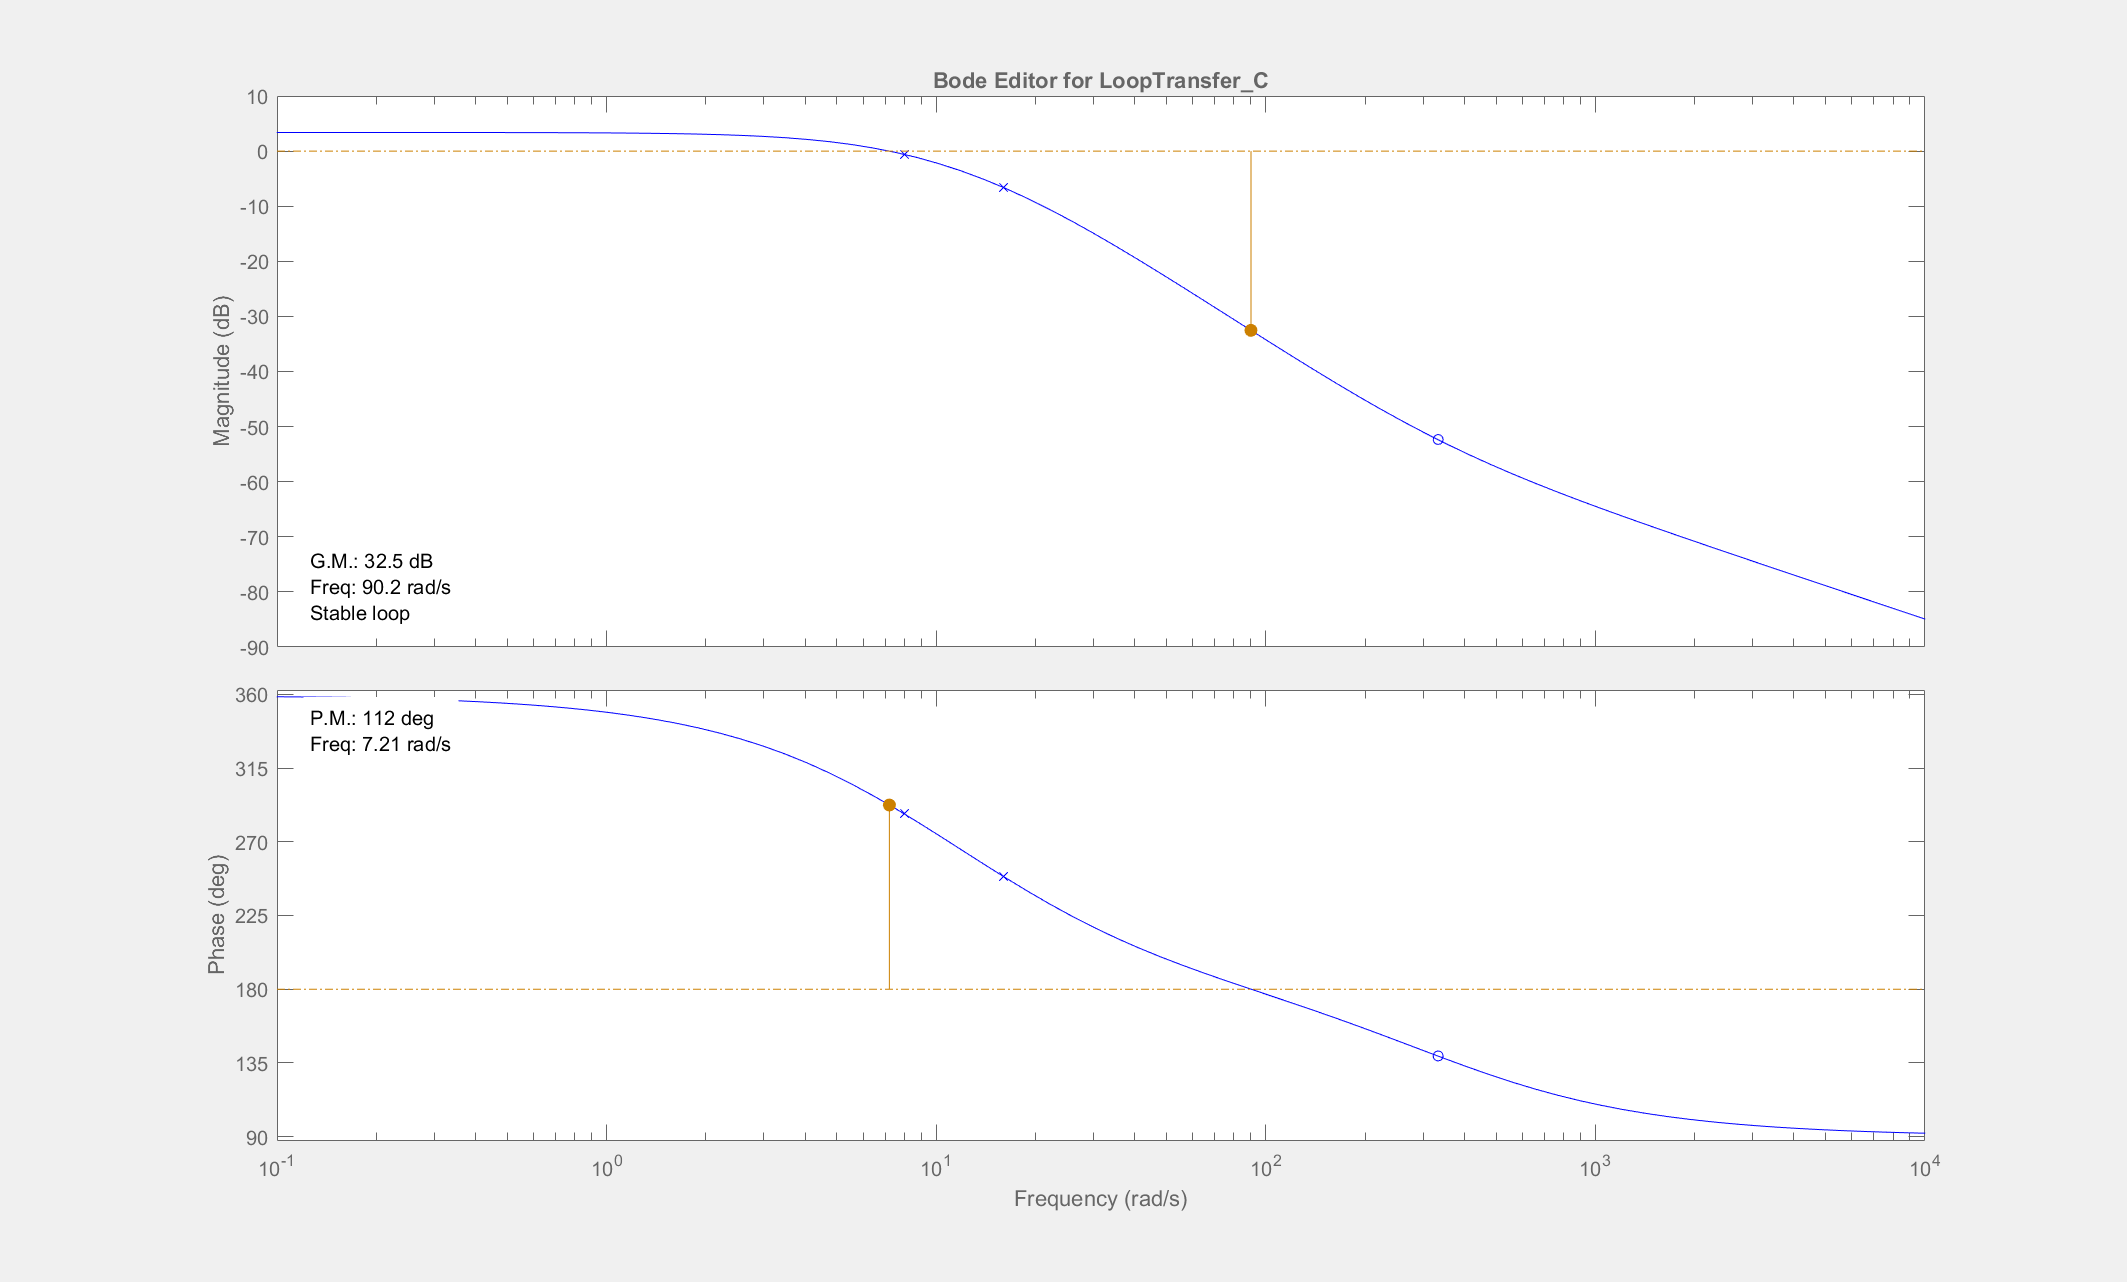

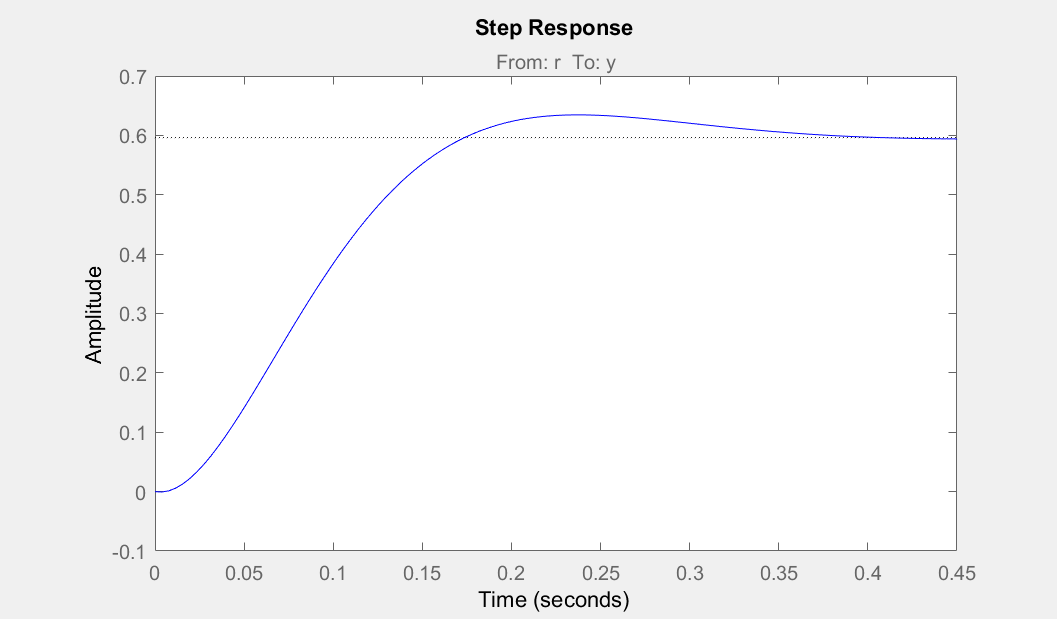

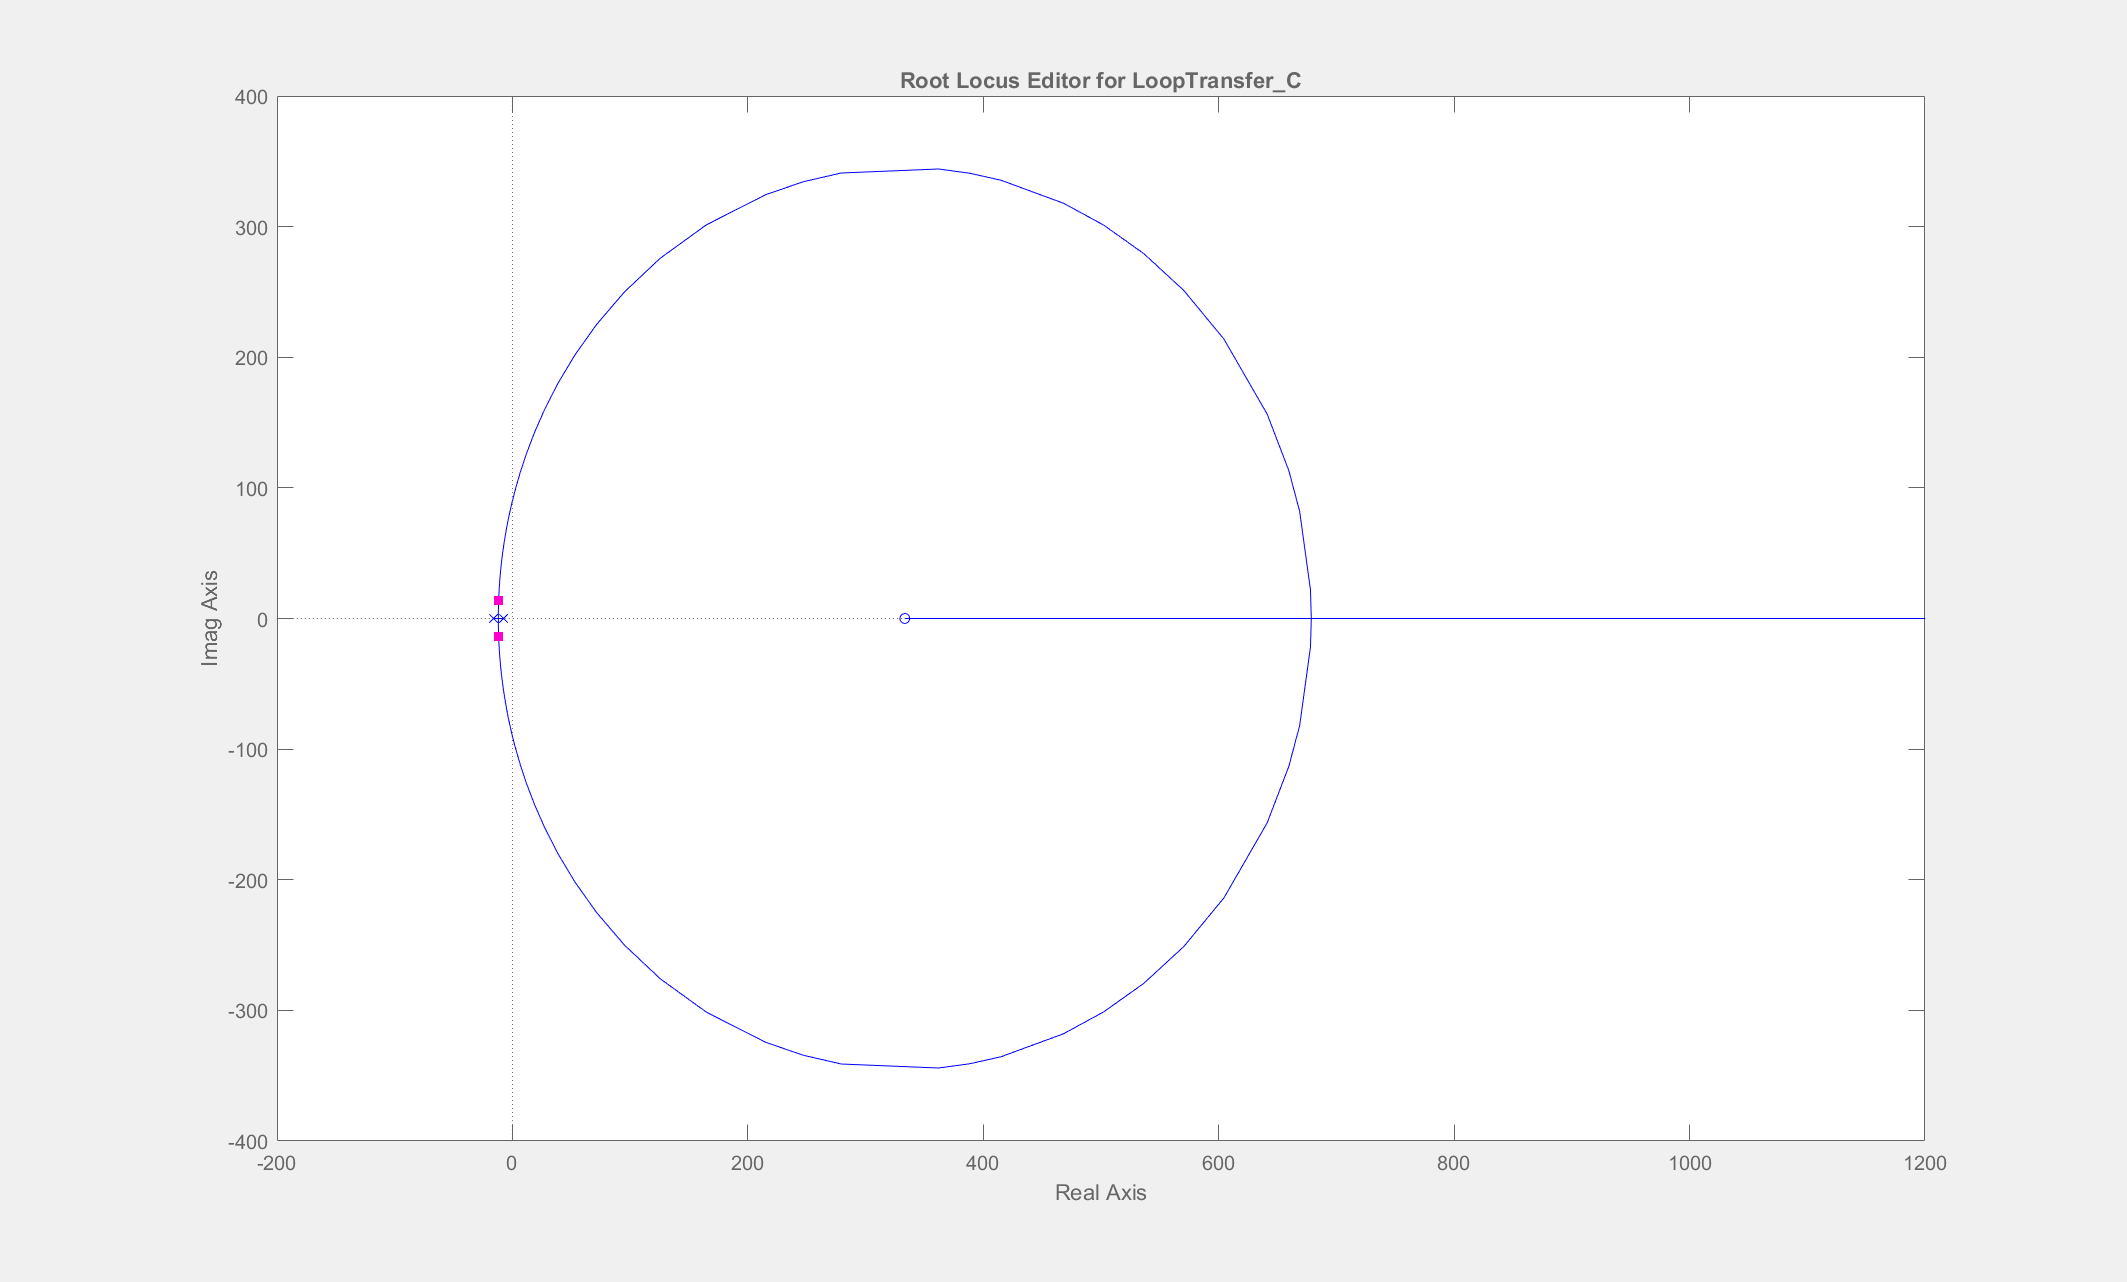

%sisotool(G3)

Ess3=10/100;
kG3=(7*c)/(2*(b^2))

kG3 = 1.4766

kC3=(1-Ess3)/(Ess3*kG3)

kC3 = 6.0952

xG3=-10;
yG3=-15;
zG3=(yG3*kC3)/xG3

zG3 = 9.1429

C3=zpk([xG3],[yG3],[zG3])

C3 =
 
  9.1429 (s+10)
  -------------
     (s+15)
 
Continuous-time zero/pole/gain model.



**Lead-Lag Compensator**

EssL3=5/100;
%Lead
kG3_LC=(7*c)/(2*(b^2))

kG3_LC = 1.4766

kC3_LC=xG3*zG3/yG3

kC3_LC = 6.0952

C3_LC=zpk([xG3],[yG3],[zG3])

C3_LC =
 
  9.1429 (s+10)
  -------------
     (s+15)
 
Continuous-time zero/pole/gain model.




%Lag
kC3_LgC=(1-EssL3)/(EssL3*kG3_LC*kC3_LC)

kC3_LgC = 2.1111

xlg3=-4;
ylg3=xlg3/kC3_LgC

ylg3 = -1.8947

C3_LgC=zpk([xlg3],[ylg3],[1])

C3_LgC =
 
    (s+4)
  ---------
  (s+1.895)
 
Continuous-time zero/pole/gain model.



C3_C=C3_LC*C3_LgC

C3_C =
 
  9.1429 (s+10) (s+4)
  -------------------
   (s+15) (s+1.895)
 
Continuous-time zero/pole/gain model.

